RC = 1; % second
w = logspace(-3,3);
z3 = 1./(1+(1i*w));
z4 = 1i*w./(1+(1i*w));

mag_z3 = 1./sqrt(1+w.^2);
mag_z4 = w./sqrt(1+w.^2);

theta_z3 = atan(sqrt(1+w.^2)./1);
theta_z4 = atan(sqrt(1+w.^2)./w);

% rho_z3 = abs(z3);
% rho_z4 = abs(z4);
% 
% theta_z3 = abs(z3);
% theta_z4 = abs(z4);

% RC = 1; % second
% w = logspace(-3,3);
% z3 = 1./(1+(1i*w));
% z4 = 1i*w./(1+(1i*w));
% 
% [theta_z3, rho_z3] = cart2pol(real(z3),imag(z3))
% [theta_z4, rho_z4] = cart2pol(real(z4),imag(z4))

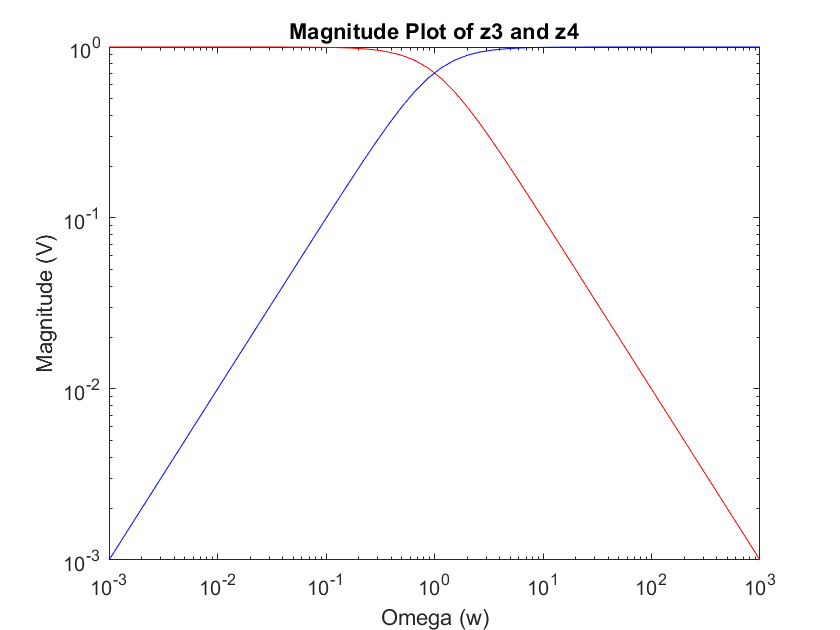

figure
loglog(w, mag_z3, 'r');
hold on
loglog(w, mag_z4, 'b');
title("Magnitude Plot of z{3} and z{4}")
xlabel("Omega (w)")
ylabel("Magnitude (V)")

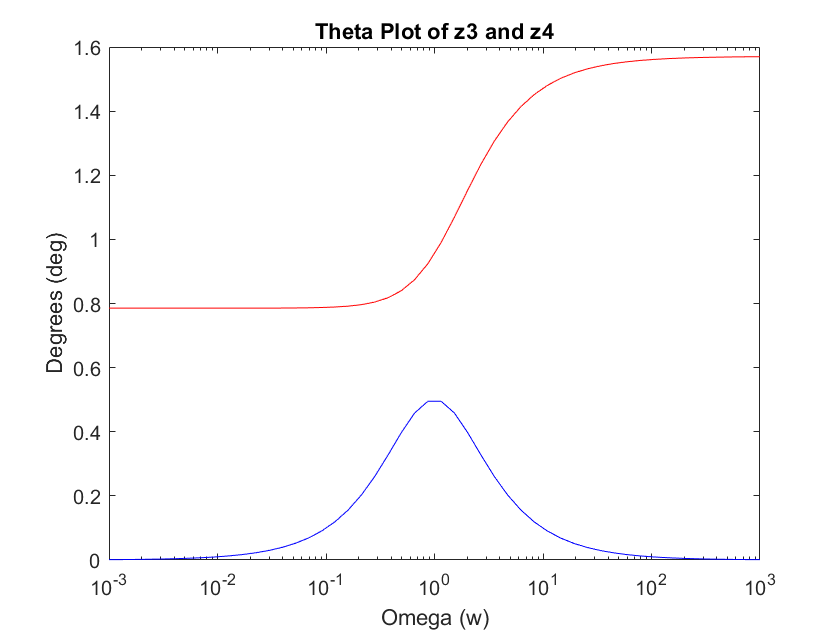

figure
semilogx(w,theta_z3,'r')
hold on
semilogx(w,imag(z4),'b')
title("Theta Plot of z{3} and z{4}")
xlabel("Omega (w)")
ylabel("Degrees (deg)")